## [Additive Manufacturing](https://apmonitor.com/pds/index.php/Main/AdditiveManufacturing)'

Additive manufacturing is the process of building from a computer controlled 3-dimensional printer. The material can be polymer (plastic), ceramic, metallic powder, liquid, or any material that is joined together through deposition, solidification, or fusion. It speeds the development of prototypes by precisely converting a computer aided design (CAD) drawing into a physical device. Additive manufacturing can be either a prototype or scaled up to full product production, but typically for applications that require customization or with low production volumes.

**Background:** A [**3D print data set of additive manufacturing test conditions**](https://apmonitor.com/pds/uploads/Main/manufacturing.txt) is available for Polylactic Acid (PLA) and Acrylonitrile Butadiene Styrene (ABS). PLA can print at lower temperatures of 180°C compared to 250°C for ABS. PLA is more brittle than ABS and is not typically suitable for high strength applications. The data was collected by researchers in the Mechanical Engineering department at Selçuk Üniversitesi on a Ultimaker S5 3D printer. The study focused on how the parameters in a specific 3D printer affects the print quality, accuracy and final part strength. This work is based on the settings and PLA or ABS filaments. Material and strength tests were carried out on a Sincotec GMBH tester capable of pulling 20 kN.

Nine parameters were adjusted for the Ultimaker S5 3D printer.

- Layer Height (mm)

- Wall Thickness (mm)

- Infill Density (%)

- Infill Pattern (Honeycomb or Grid)

- Nozzle Temperature (ºC)

- Bed Temperature (ºC)

- Print Speed (mm/s)

- Material (PLA or ABS)

- Fan Speed (%)

After the part was manufactured, three parameters were measured for each product.

- Roughness (µm)

- Tension Strength (MPa)

- Elongation (%)

The labeled data is a combination of PLA and ABS material, print patterns, and conditions with 66 samples from a first repository and 50 samples from a second repository. The [**combined set**](https://apmonitor.com/pds/uploads/Main/manufacturing.txt) is 70 samples with the duplicates removed and one outlier added. The label associated with each filament is *pla* or *abs*. The print pattern is *grid* or *honeycomb*. [**One-hot encoding**](https://en.wikipedia.org/wiki/One-hot) translates character labels into a binary representation (0 or 1) for classification.

 [**Additive Manufacturing Data**](https://apmonitor.com/pds/uploads/Main/manufacturing.txt)

## Part 1: Data Visualization and Cleansing

Generate summary statistics with a profiling report to [**statistically characterize the data**](https://apmonitor.com/pds/index.php/Main/StatisticsMath). Use box plots to identify the one outlier in the data. Remove the row that contains the outlier from the data set. Generate a pair plot and correlation matrix. What factors are highly correlated to *Material (PLA or ABS)* and *Tension Strength (MPa)*?

%Clear proceeding data 
clear;
%Load data from URL 
url = "https://apmonitor.com/pds/uploads/Main/manufacturing.txt";
data = readtable(url);

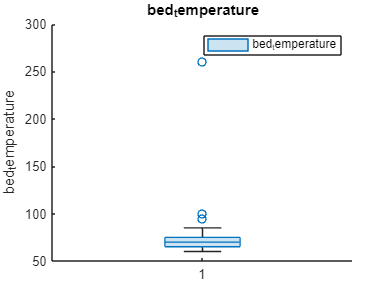

% Create boxchart of data.bed_temperature
h2 = boxchart(data.bed_temperature,"DisplayName","bed_temperature");

% Add ylabel, title, and legend
ylabel("bed_temperature")
title("bed_temperature")
legend

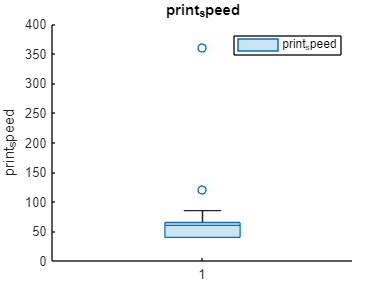

% Create boxchart of data.print_speed
h = boxchart(data.print_speed,"DisplayName","print_speed");

% Add ylabel, title, and legend
ylabel("print_speed")
title("print_speed")
legend


% Fill outliers
[cleaned, TFrm] = rmoutliers(data.bed_temperature,"percentiles",[5 95]);

data_clean = data(~TFrm,:);

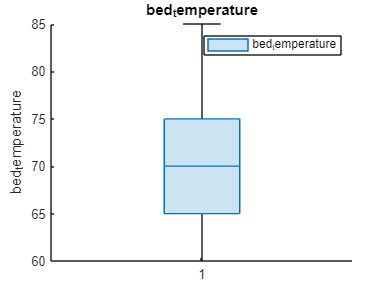

% Create boxchart of data_clean.bed_temperature
h3 = boxchart(data_clean.bed_temperature,"DisplayName","bed_temperature");

% Add ylabel, title, and legend
ylabel("bed_temperature")
title("bed_temperature")
legend

data_clean.material = categorical(data_clean.material, {'abs','pla'},{'0','1'});
data_clean.material=double(data_clean.material);
data_clean.infill_pattern = categorical(data_clean.infill_pattern, {'grid','honeycomb'},{'0','1'});
data_clean.infill_pattern = double(data_clean.infill_pattern);


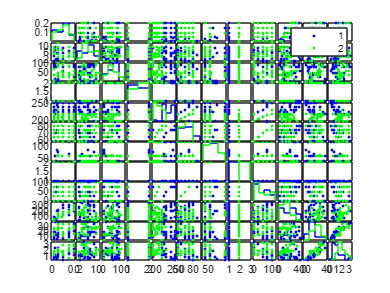

%%Generate a pair plot 

figure;
gplotmatrix(table2array(data_clean),[], data_clean.material)

% Print Statistics Values
fprintf('Layer Height=')

Layer Height=

statistics(data_clean.("layer_height"))

ans = struct with fields:
    count: 67
     mean: 0.0982
      std: 0.0621
      min: 0.0200
      max: 0.2000
       Q1: 0.0525
       Q2: 0.1000
       Q3: 0.1500


fprintf('wall thickness')

wall thickness

statistics(data_clean.("wall_thickness"))

ans = struct with fields:
    count: 67
     mean: 5.4701
      std: 2.9681
      min: 1
      max: 12
       Q1: 3
       Q2: 6
       Q3: 8


fprintf('Infill Density')

Infill Density

statistics(data_clean.("infill_density"))

ans = struct with fields:
    count: 67
     mean: 53.0149
      std: 27.4924
      min: 10
      max: 100
       Q1: 30
       Q2: 50
       Q3: 80


fprintf('Nozzle Temperature')

Nozzle Temperature

statistics(data_clean.("nozzle_temperature"))

ans = struct with fields:
    count: 67
     mean: 221.5672
      std: 14.7250
      min: 200
      max: 250
       Q1: 210
       Q2: 220
       Q3: 230


fprintf('Bed Temperature')

Bed Temperature

statistics(data_clean.("bed_temperature"))

ans = struct with fields:
    count: 67
     mean: 69.7015
      std: 7.2760
      min: 60
      max: 85
       Q1: 65
       Q2: 70
       Q3: 75


fprintf('Print speed')

Print speed

statistics(data_clean.("print_speed"))

ans = struct with fields:
    count: 67
     mean: 65.0746
      std: 29.1871
      min: 40
      max: 120
       Q1: 40
       Q2: 60
       Q3: 63.7500


fprintf('Fan Speed')

Fan Speed

statistics(data_clean.("fan_speed"))

ans = struct with fields:
    count: 67
     mean: 48.1791
      std: 35.6778
      min: 0
      max: 100
       Q1: 25
       Q2: 50
       Q3: 75


fprintf('roughness')

roughness

statistics(data_clean.("roughness"))

ans = struct with fields:
    count: 67
     mean: 159.3134
      std: 95.6668
      min: 21
      max: 368
       Q1: 75
       Q2: 145
       Q3: 220


fprintf('Tension Strength')

Tension Strength

statistics(data_clean.("tension_strength"))

ans = struct with fields:
    count: 67
     mean: 19.7015
      std: 8.8950
      min: 4
      max: 37
       Q1: 12
       Q2: 18
       Q3: 27


fprintf('Infill Pattern')

Infill Pattern

statistics(data_clean.("infill_pattern"))

ans = struct with fields:
    count: 67
     mean: 1.5224
      std: 0.5033
      min: 1
      max: 2
       Q1: 1
       Q2: 2
       Q3: 2


fprintf('Material')

Material

statistics(data_clean.("material"))

ans = struct with fields:
    count: 67
     mean: 1.4776
      std: 0.5033
      min: 1
      max: 2
       Q1: 1
       Q2: 1
       Q3: 2


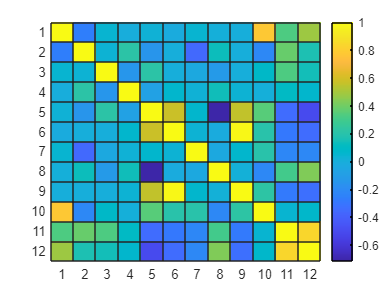

%%Create correlation matrix 
R = corrcoef(table2array(data_clean));

% Plot the heat map
figure;
heatmap(R,'Colormap',parula)

## Part 2: Prediction and Analysis

Examination of a Spearman's "rho" based correlation matrix versus the one presented above based on R^2 values shows little change. We are primarily interested in predicting material and tension strength. For material, nozzle temperature and elongation seem to have the strongest correlations. For tension strength the strongest correlates are layer height, nozzle temperature, and material; disregarding elongation as it is not a specifiable machine input.

%%%Scale Data 
sc_data = rescale(table2array(data_clean))

sc_data =     0.0001    0.0217    0.2446    0.0027    0.5978    0.1630    0.1087    0.0027         0    0.0679    0.0489    0.0033
    0.0001    0.0190    0.2446    0.0054    0.6114    0.1766    0.1087    0.0027    0.0679    0.0870    0.0435    0.0038
    0.0001    0.0027    0.2174    0.0027    0.6250    0.1902    0.1087    0.0027    0.1359    0.1087    0.0217    0.0022
    0.0001    0.0109    0.1902    0.0054    0.6522    0.2038    0.1087    0.0027    0.2038    0.1848    0.0272    0.0014
    0.0001    0.0163    0.2446    0.0027    0.6793    0.2174    0.1087    0.0027    0.2717    0.2500    0.0136    0.0019
    0.0001    0.0272    0.1087    0.0054    0.5435    0.1630    0.1087    0.0054         0    0.1630    0.0652    0.0030
    0.0001    0.0136    0.0272    0.0027    0.5571    0.1766    0.1087    0.0054    0.0679    0.1495    0.0326    0.0035
    0.0001    0.0272    0.0272    0.0054    0.5707    0.1902    0.1087    0.0054    0.1359    0.0571    0.0380    0.0041
    0.0001    0.0245  

sc_data = array2table(sc_data)

sc_data = 67×12 table
     sc_data1     sc_data2     sc_data3    sc_data4     sc_data5    sc_data6    sc_data7    sc_data8     sc_data9    sc_data10    sc_data11    sc_data12
    __________    _________    ________    _________    ________    ________    ________    _________    ________    _________    _________    _________

    5.4348e-05     0.021739     0.24457    0.0027174    0.59783     0.16304      0.1087     0.0027174           0    0.067935     0.048913     0.0032609
    5.4348e-05     0.019022     0.24457    0.0054348    0.61141     0.17663      0.1087     0.0027174    0.067

sc_data.Properties.VariableNames = data_clean.Properties.VariableNames

sc_data = 67×12 table
    layer_height    wall_thickness    infill_density    infill_pattern    nozzle_temperature    bed_temperature    print_speed    material     fan_speed    roughness    tension_strength    elongation
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________    __________

     5.4348e-05        0.021739           0.24457         0.0027174            0.59783              0.16304           0.1087      0.0027174           0     0.067935     


%implement 80/20 train/test split
[r,c] = size(sc_data)

r = 67

c = 12

cv = cvpartition(r,'HoldOut',0.20);
idx = cv.test;

trainData = sc_data(~idx,:); 
testData = sc_data(idx,:);

Z_score = fscchi2(trainData,trainData.material)

Z_score =      8     5    11    12     4     2     3    10     9     1     7     6


X = categorical(trainData.Properties.VariableNames)
bar(X,Z_score)


tiledlayout(4,2)

%Naive Bayes
nb = fitcnb(trainData, 'material')

nb =   ClassificationNaiveBayes
            PredictorNames: {'layer_height'  'wall_thickness'  'infill_density'  'infill_pattern'  'nozzle_temperature'  'bed_temperature'  'print_speed'  'fan_speed'  'roughness'  'tension_strength'  'elongation'}
              ResponseName: 'material'
     CategoricalPredictors: []
                ClassNames: [0.0027 0.0054]
            ScoreTransform: 'none'
           NumObservations: 54
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {2×11 cell}


  Properties, Methods


labels = predict(nb, testData);
nexttile
confusionchart(testData.material,labels)
title("Naive Bayes Prediction")

%Nearest Neighbors
knn = fitcknn(trainData,'material')

knn =   ClassificationKNN
           PredictorNames: {'layer_height'  'wall_thickness'  'infill_density'  'infill_pattern'  'nozzle_temperature'  'bed_temperature'  'print_speed'  'fan_speed'  'roughness'  'tension_strength'  'elongation'}
             ResponseName: 'material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 54
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


labels = predict(knn, testData);
nexttile
confusionchart(testData.material,labels)
title("Nearest Neighbors Prediction")

%Classification Tree
tree = fitctree(trainData,'material')

tree =   ClassificationTree
           PredictorNames: {'layer_height'  'wall_thickness'  'infill_density'  'infill_pattern'  'nozzle_temperature'  'bed_temperature'  'print_speed'  'fan_speed'  'roughness'  'tension_strength'  'elongation'}
             ResponseName: 'material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 54


  Properties, Methods


labels = predict(tree, testData);
nexttile
confusionchart(testData.material,labels)
title("Classification Tree Prediction")

%Discriminant Analysis
disc = fitcdiscr(trainData, 'material')

disc =   ClassificationDiscriminant
           PredictorNames: {'layer_height'  'wall_thickness'  'infill_density'  'infill_pattern'  'nozzle_temperature'  'bed_temperature'  'print_speed'  'fan_speed'  'roughness'  'tension_strength'  'elongation'}
             ResponseName: 'material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 54
              DiscrimType: 'linear'
                       Mu: [2×11 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


labels = predict(disc, testData);
nexttile
confusionchart(testData.material,labels)
title("Discriminant Analysis Prediction")

%Support Vector Machine Classification
vect = fitcsvm(trainData,'material')

vect =   ClassificationSVM
           PredictorNames: {'layer_height'  'wall_thickness'  'infill_density'  'infill_pattern'  'nozzle_temperature'  'bed_temperature'  'print_speed'  'fan_speed'  'roughness'  'tension_strength'  'elongation'}
             ResponseName: 'material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 54
                    Alpha: [48×1 double]
                     Bias: 0.3578
         KernelParameters: [1×1 struct]
           BoxConstraints: [54×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [54×1 logical]
                   Solver: 'SMO'


  Properties, Methods


labels = predict(vect, testData);
nexttile
confusionchart(testData.material,labels)
title("Support Vector Machine Prediction")

%Classification Ensemble
ensemble = fitcensemble(trainData,'material')

ensemble =   ClassificationEnsemble
           PredictorNames: {'layer_height'  'wall_thickness'  'infill_density'  'infill_pattern'  'nozzle_temperature'  'bed_temperature'  'print_speed'  'fan_speed'  'roughness'  'tension_strength'  'elongation'}
             ResponseName: 'material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 54
               NumTrained: 100
                   Method: 'LogitBoost'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: [100×1 double]
       FitInfoDescription: {2×1 cell}


  Properties, Methods


labels = predict(ensemble, testData);
nexttile
confusionchart(testData.material,labels)
title("Classification Ensemble Prediction")

%Neural Network
nn = fitcnet(trainData,'material')

nn =   ClassificationNeuralNetwork
           PredictorNames: {'layer_height'  'wall_thickness'  'infill_density'  'infill_pattern'  'nozzle_temperature'  'bed_temperature'  'print_speed'  'fan_speed'  'roughness'  'tension_strength'  'elongation'}
             ResponseName: 'material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'none'
          NumObservations: 54
               LayerSizes: 10
              Activations: 'relu'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [43×7 table]


  Properties, Methods


labels = predict(nn, testData);
nexttile
confusionchart(testData.material,labels)
title("Neural Network Prediction")

%Generalized Additive Model
genadd = fitcgam(trainData,'material')

genadd =   ClassificationGAM
           PredictorNames: {'layer_height'  'wall_thickness'  'infill_density'  'infill_pattern'  'nozzle_temperature'  'bed_temperature'  'print_speed'  'fan_speed'  'roughness'  'tension_strength'  'elongation'}
             ResponseName: 'material'
    CategoricalPredictors: []
               ClassNames: [0.0027 0.0054]
           ScoreTransform: 'logit'
                Intercept: -2.4962
          NumObservations: 54


  Properties, Methods


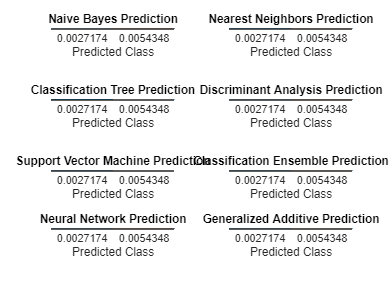

labels = predict(genadd, testData);
nexttile
confusionchart(testData.material,labels)
title("Generalized Additive Prediction")

### **Regression Practice**

** Use 3 regression methods. Possible **[**regression methods**](https://apmonitor.com/pds/notebooks/06_regression.html)** are:**

- [**Linear Regression**](https://apmonitor.com/pds/index.php/Main/LinearRegression)

- [**Neural Network (Deep Learning)**](https://apmonitor.com/pds/index.php/Main/MultilayerPerceptronNeuralNetwork)

- [**K-Nearest Neighbors**](https://apmonitor.com/pds/index.php/Main/KNearestNeighborsRegression)

- [**Support Vector Regressor**](https://apmonitor.com/pds/index.php/Main/SupportVectorRegressor)

- [**XGBoost Regressor**](https://apmonitor.com/pds/index.php/Main/XGBoostRegressor)

There is concern that PLA has less strength than ABS for additive manufacturing. Compare the PLA and ABS predicted strength for all of the test points. One way to compare the strength is to change the *PLA* material to *ABS* and recalculate the predicted *Tension Strength (MPa)*.

Examples chosen: Linear Regression, Neural Network, K-Nearest Neighbors 

% %%use Tension strength data

%obtain all data from layer_height to tension_strength
lm_input = trainData(:,1:11) 

lm_input = 54×11 table
    layer_height    wall_thickness    infill_density    infill_pattern    nozzle_temperature    bed_temperature    print_speed    material     fan_speed    roughness    tension_strength
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________

     5.4348e-05        0.021739           0.24457         0.0027174            0.59783              0.16304           0.1087      0.0027174           0     0.067935         0.048913    
     5.4348e-05        0.019022           0.



%Linear Regression 
mdl = fitlm(lm_input)

mdl = Linear regression model:
    tension_strength ~ 1 + layer_height + wall_thickness + infill_density + infill_pattern + nozzle_temperature + bed_temperature + print_speed + material + fan_speed + roughness

Estimated Coefficients:
                          Estimate        SE        tStat        pValue  
                          _________    ________    ________    __________

    (Intercept)           -0.044919     0.09574    -0.46917       0.64131
    layer_height             104.81      17.633      5.9439    4.4112e-07
    wall_thickness          0.83751     0.24203      3.4604     0.0012304
    infill_density         0.084973    0.023743      3.5788     0.0008707
    infill_pattern          0.28214      1.3097     0.21543       0.83045
    nozzle_temper

predictions = predict(mdl,testData(:,1:10))

predictions =     0.0602
    0.0517
    0.0550
    0.0596
    0.0573
    0.0696
    0.0499
    0.0711
    0.0883
    0.0768


R_squared = rsq(table2array(testData(:,11)),predictions)

SSresid = 0.0117

SStotal = 0.0085

R_squared = -0.3764

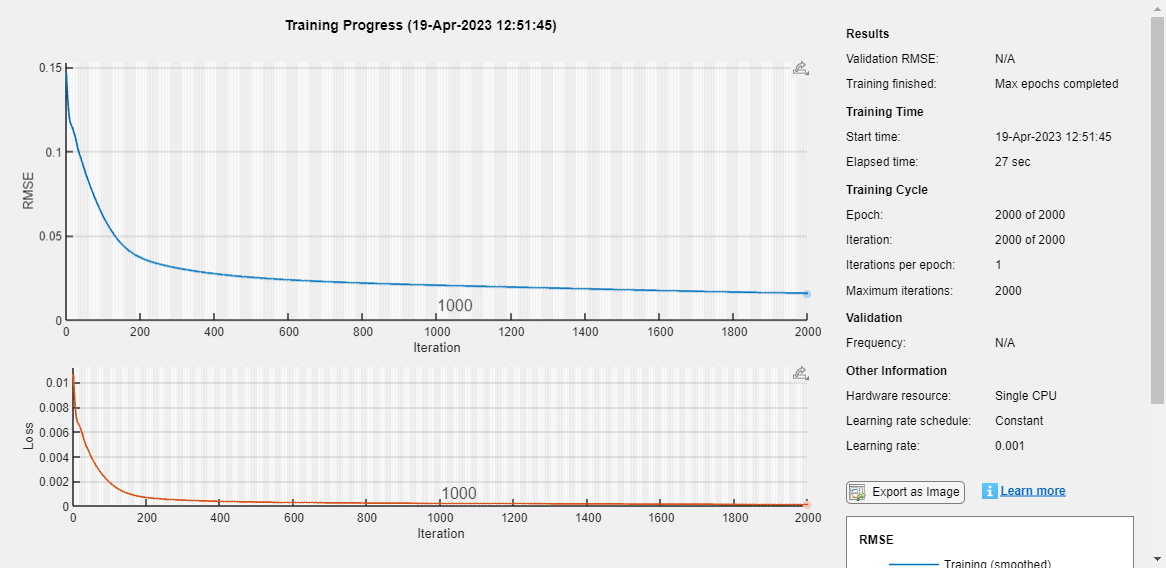



%%Neural Network regressor
layers = [
    sequenceInputLayer(10,"Name","input")
    fullyConnectedLayer(2,"Name","fc_2")
    fullyConnectedLayer(2,"Name","fc")
    tanhLayer("Name","tanh")
    fullyConnectedLayer(2,"Name","fc_1")
    fullyConnectedLayer(1,"Name","fc_3")
    regressionLayer("Name","regressionoutput")];
%%% Set options for train 
options = trainingOptions("adam", ...
    MaxEpochs=2000, ...
    Verbose=false, ...
    Plots="training-progress");
%%Train model to dataset 

net = trainNetwork(table2array(trainData(:,1:10))', table2array(trainData(:,11))', layers,options);


%%Find R^2 for neural net 
y_val = predict(net,table2array(testData(:,1:10))');
R_squared_net = rsq(y_val',table2array(testData(:,11)))

SSresid = single
0.0093

SStotal = single
0.0017

R_squared_net = single
-4.3445

%%%Support Vector Regression 
mdl_vec = fitrsvm(trainData(:,1:10),trainData(:,11)) 

mdl_vec =   RegressionSVM
           PredictorNames: {'layer_height'  'wall_thickness'  'infill_density'  'infill_pattern'  'nozzle_temperature'  'bed_temperature'  'print_speed'  'material'  'fan_speed'  'roughness'}
             ResponseName: 'tension_strength'
    CategoricalPredictors: []
        ResponseTransform: 'none'
                    Alpha: [48×1 double]
                     Bias: 0.1872
         KernelParameters: [1×1 struct]
          NumObservations: 54
           BoxConstraints: [54×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [54×1 logical]
                   Solver: 'SMO'


  Properties, Methods


pred_vec = predict(mdl_vec,testData(:,1:10))

pred_vec =     0.0605
    0.0530
    0.0443
    0.0337
    0.0450
    0.0500
    0.0349
    0.0715
    0.0971
    0.0744


R_squared_net = rsq(pred_vec,table2array(testData(:,11)))

SSresid = 0.0134

SStotal = 0.0043

R_squared_net = -2.1540



%%%Graph data
figure
testData_graph = table2array(testData(:,11))

testData_graph =     0.0652
    0.1005
    0.0707
    0.0788
    0.0924
    0.0598
    0.0109
    0.0761
    0.0761
    0.0380


scatter(testData_graph,table2array(testData(:,11)))
hold

Current plot held


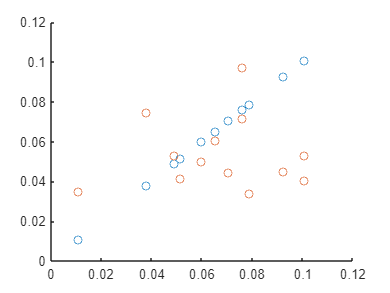

scatter(testData_graph,pred_vec)

%%% Recalculate predicted vals for PLA if changed to ABS %%%
dfPl = (testData.material < 0.005) == 0 

dfPl = 13×1 logical array
   1
   0
   1
   1
   1
   1
   1
   0
   1
   1


test_Pl = testData(dfPl,:)

test_Pl = 8×12 table
    layer_height    wall_thickness    infill_density    infill_pattern    nozzle_temperature    bed_temperature    print_speed    material     fan_speed    roughness    tension_strength    elongation
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________    __________

     5.4348e-05        0.027174            0.1087         0.0054348            0.54348              0.16304           0.1087      0.0054348           0      0.16304      


%%%Run three tests on Pla materials 


pl_net_pred = predict(net,table2array(test_Pl(:,1:10))');
predictions_pl = predict(mdl,test_Pl(:,1:10))

predictions_pl =     0.0602
    0.0550
    0.0596
    0.0573
    0.0696
    0.0499
    0.0883
    0.0768


pred_vec_pl = predict(mdl_vec,test_Pl(:,1:10))

pred_vec_pl =     0.0605
    0.0443
    0.0337
    0.0450
    0.0500
    0.0349
    0.0971
    0.0744


%%Now do it for Abs 
test_Ab = test_Pl

test_Ab = 8×12 table
    layer_height    wall_thickness    infill_density    infill_pattern    nozzle_temperature    bed_temperature    print_speed    material     fan_speed    roughness    tension_strength    elongation
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________    __________

     5.4348e-05        0.027174            0.1087         0.0054348            0.54348              0.16304           0.1087      0.0054348           0      0.16304      

test_Ab.material = test_Ab.material / 2

test_Ab = 8×12 table
    layer_height    wall_thickness    infill_density    infill_pattern    nozzle_temperature    bed_temperature    print_speed    material     fan_speed    roughness    tension_strength    elongation
    ____________    ______________    ______________    ______________    __________________    _______________    ___________    _________    _________    _________    ________________    __________

     5.4348e-05        0.027174            0.1087         0.0054348            0.54348              0.16304           0.1087      0.0027174           0      0.16304      


%%%Run three tests on Abs materials 
ab_net_pred = predict(net,table2array(test_Ab(:,1:10))')

ab_net_pred = 1×8 single row vector
    0.0550    0.0458    0.0457    0.0511    0.0503    0.0329    0.0753    0.0547


predictions_ab = predict(mdl,test_Ab(:,1:10))

predictions_ab =     0.0435
    0.0384
    0.0429
    0.0407
    0.0530
    0.0332
    0.0717
    0.0601


pred_vec_ab = predict(mdl_vec,test_Ab(:,1:10))

pred_vec_ab =     0.0604
    0.0443
    0.0337
    0.0449
    0.0500
    0.0349
    0.0971
    0.0744


%%%Create bar graph to compare performance of models 
labels = categorical({'Neural Net','Vector Regression','Linear Regression'})

labels = 1×3 categorical array
     Neural Net      Vector Regression      Linear Regression 



test_res = [mean(pl_net_pred),mean(ab_net_pred);
    mean(pred_vec_pl), mean(pred_vec_ab);
    mean(predictions_pl), mean(predictions_ab)]

test_res = 3×2 single matrix
    0.0522    0.0514
    0.0550    0.0549
    0.0646    0.0479


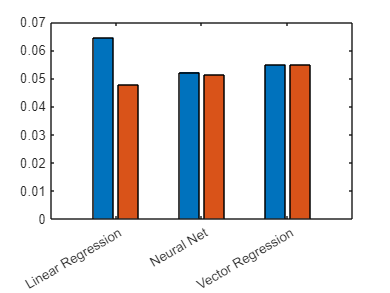

figure
bar(labels,test_res)


%%%Note: Orange == abs and blue == pla 

As you can see, if the material is "Pla", it will be predicted as having a higher tensile strenght on average than that of "Abs" 

function r2 = rsq(y1,y2)
    yresid = y1 - y2;
    SSresid = sum(yresid.*yresid);
    SSresid
    [V,md ] = var(y1);
    [r,c]=size(y1);
    SStotal = r*V;
    SStotal
    r2 = 1 - SSresid./SStotal;
end
function statistics = statistics(data)
    statistics.count = numel(data); % count
    statistics.mean = mean(data); % mean
    statistics.std = std(data); % standard deviation
    statistics.min = min(data); % min
    statistics.max = max(data); % max
    statistics.Q1 = prctile(data,25); % 1st quartile (25th percentile)
    statistics.Q2 = prctile(data,50); % 2nd quartile (50th percentile) = median
    statistics.Q3 = prctile(data,75); % 3rd quartile (75th percentile)
end





